## fplot

- `fplot(@fun,lims)` - plots the function fun between the x-axis limits

- `lims = [xmin xmax ymin ymax]` - axis limits

- The function `fun(x)` must return a row vector for each element of vector x.

## AXIS Control

- axis scaling and appearance

- `axis([xmin xmax ymin ymax])`

- Sets scaling for the x- and y-axes on the current plot

- `axis auto` - returns the axis scaling to its default, automatic mode.

- `axis off` - turns off all axis labelling,tick marks and background.

- `axis on` - turms axis labeling, tick marks and background.

- `axis equal` - makes both axes equal.

## 3D Plot

the general syntax for plot3 command is

plot3(x,y,z,'*style-option*')

`plot3` - plots curves in space,

`stem3` - creates discrete data plot with stems in 3-D,

`bar3` - plots 3-D bar graph,

`bar3h` - plots 3-D horizontal bar graph,

`pie3` - makes 3-D pie chart,

`comet3` - makes animated 3-D line plot,

`fill3` - draws filled 3-D polygons,

`contour3` - makes 3-D contour plots,

`quivers` - draws vector fields in 3-D,

`scatter3` - makes scatter plots in 3-D,

`mesh` - draws 3-D mesh surfaces (wire-frame),

`meshc` - draws 3-D mesh surfaces along with contours,

`meshz` - draws 3-D mesh surfaces with reference plane curtains,

`surf` - creates 3-D surface plots,

`surfc` - creates 3-D surface plots along with contours,

`surfl` - creates 3-D surface plots with specified light source,

`trimesh` - mesh plot with triangles,

`trisurf` - surface plot with triangles,

`slice` - draws a volumetric surface with slices,

`waterfall` - creates a waterfall plot of 3-D data,

`cylinder` - generates a cylinder,

`ellipsoid` - generates an ellipsoid, and

`sphere` - generates a sphere.

## 3D Plot: Question 1

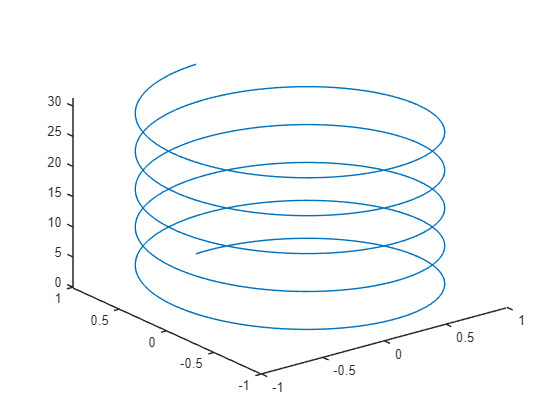

t = 0:pi/50:10*pi;
plot3(sin(t),cos(t),t)

## Surface Plot: Question 2

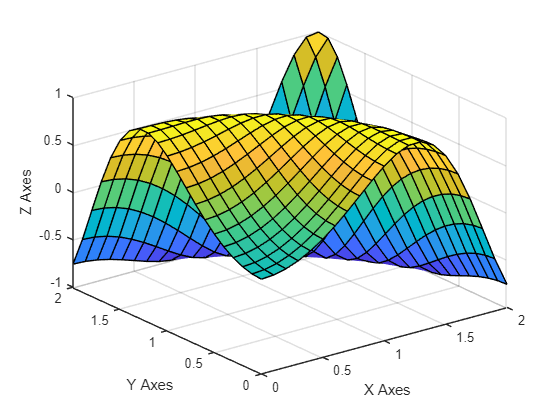

x = 0:0.1:2;
y = 0:0.1:2;
[xx,yy] = meshgrid(x,y);
zz = sin(xx.^2+yy.^2);
surf(xx,yy,zz)
xlabel('X Axes')
ylabel('Y Axes')
zlabel('Z Axes')

## Question 3

Plot voltage vs time for various RC time constants


$$\frac{\upsilon }{V}=e^{-\frac{t}{\tau }}$$


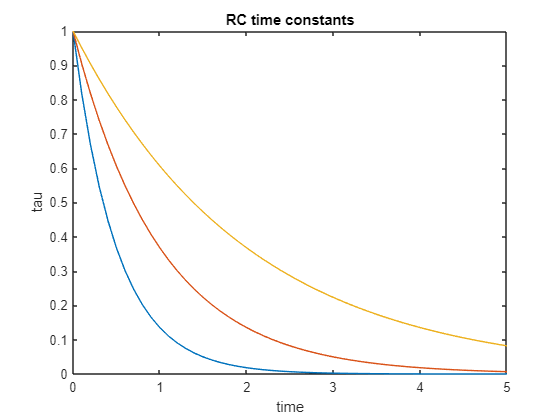

time = 0:0.1:5;
tau = [0.5 1.0 2.0];
[TIME TAU] = meshgrid(time,tau);
V = exp(-TIME./TAU);
plot(time,V)
xlabel('time')
ylabel('tau')
title('RC time constants')

## Question 4

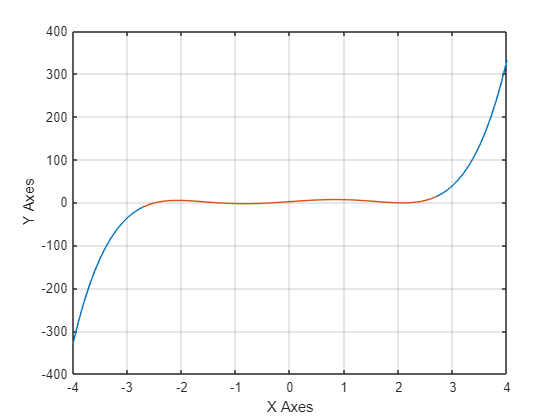

x1 = -4:0.1:4;
x2 = -2.7:0.1:2.7;
f1 = 0.6*x1.^5 - 5*x1.^3+9*x1+2;
f2 = 0.6*x2.^5 - 5*x2.^3+9*x2+2;
plot(x1,f1,x2,f2)
grid on
xlabel('X Axes')
ylabel('Y Axes')

## Question 5

f = @(x)(x^2 - x + 1)/(x^2 + x + 1);
l = [-10,10];
fplot(f,l)

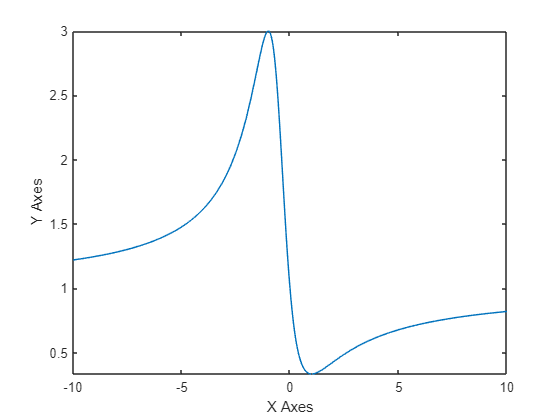

xlabel('X Axes')
ylabel('Y Axes')

## Question 6

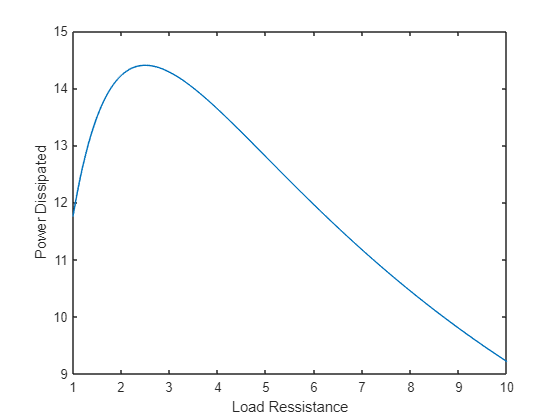

RL = 1:0.01:10;
Vs = 12;
Rs = 2.5;
P = (Vs^2*RL)./(RL+Rs).^2;
plot(RL,P)
xlabel('Load Ressistance')
ylabel('Power Dissipated')